# **FEM2D: Thermal convection problems using Quadrilateral Elements**

Consider the thermal Boundary value problem,

                                       
$$
-k_{c}\frac{\partial^{2} T}{\partial x^{2}}-k_{c} \frac{\partial^{2} T}{\partial y^{2}} = f(x,y),\quad (x,y)\in \Omega = [0,5]\times[0,2]\setminus B^{2}_{1/2}(1,1),
$$


with $k_{c} = 1$, $f\equiv 0$, and boundary conditions:

   
$$\bullet\ T(x,0) = 10^{\circ}\text{C},\ x\in[0,5],\\ \\
\bullet\ T(x,y) = 50^{\circ}\text{C}, \ (x,y) \in\partial B^{2}_ {1/2}(1,1),\\ \\
\bullet\ \frac{\partial T}{\partial x}(0,y) = \frac{\partial T}{\partial x}(5,y) = 0,\ y\in [0,2],\\ \\
\bullet\ k_{c}\displaystyle\frac{\partial T}{\partial y}(x,2) + \beta \left(T(x,2)-T_{\infty}\right) = 0,\ x\in [0,5]\ \text{ and }\ \beta =2,\, T_{\infty} = -5^{\circ}\text{C}\ \text{(i.e., convection on the top boundary, $x\in[0,5]$, $y=2$, with $\beta = 2$\, and $T_{\infty}=-5^{\circ}$C).} $$


(see figure).

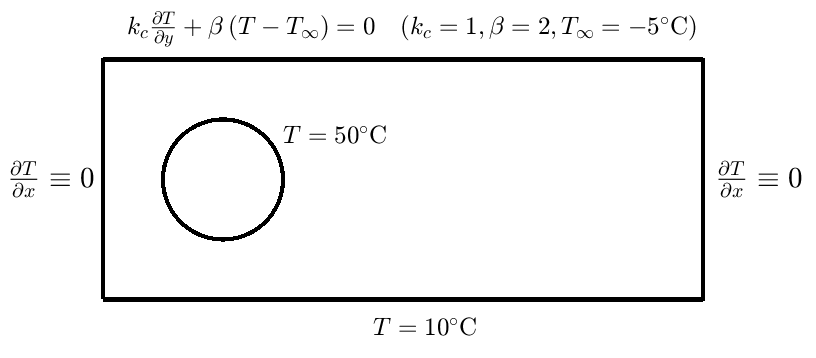

Use the FEM with the mesh given in `the` file `meshPlacaForatQuad.m` to find the temperature distribution on $\Omega$.

clearvars
close all

kc = 1.0;

a11 = kc;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f   = 0.0;

tempCirc = 50.0;
tempBot = 10.0;
beta = 2;
Tinf = -5;

p=[1.5, 1.2]; %For exercise 1


eval('meshPlacaForatQuad')

numNod = size(nodes,1);
numElem = size(elem,1);

numbering = 0;
plotElementsOld(nodes, elem, numbering);
hold on


Let's pick the nodes at the top, at the bottom and at the circle

nodesTop = find(nodes(:,2) > 1.99);
nodesBot = find(nodes(:,2) < 0.01);
nodesCirc = find(sqrt((nodes(:,1)-1).^2 + (nodes(:,2)-1).^2)< 0.501);

And plot the selected nodes...

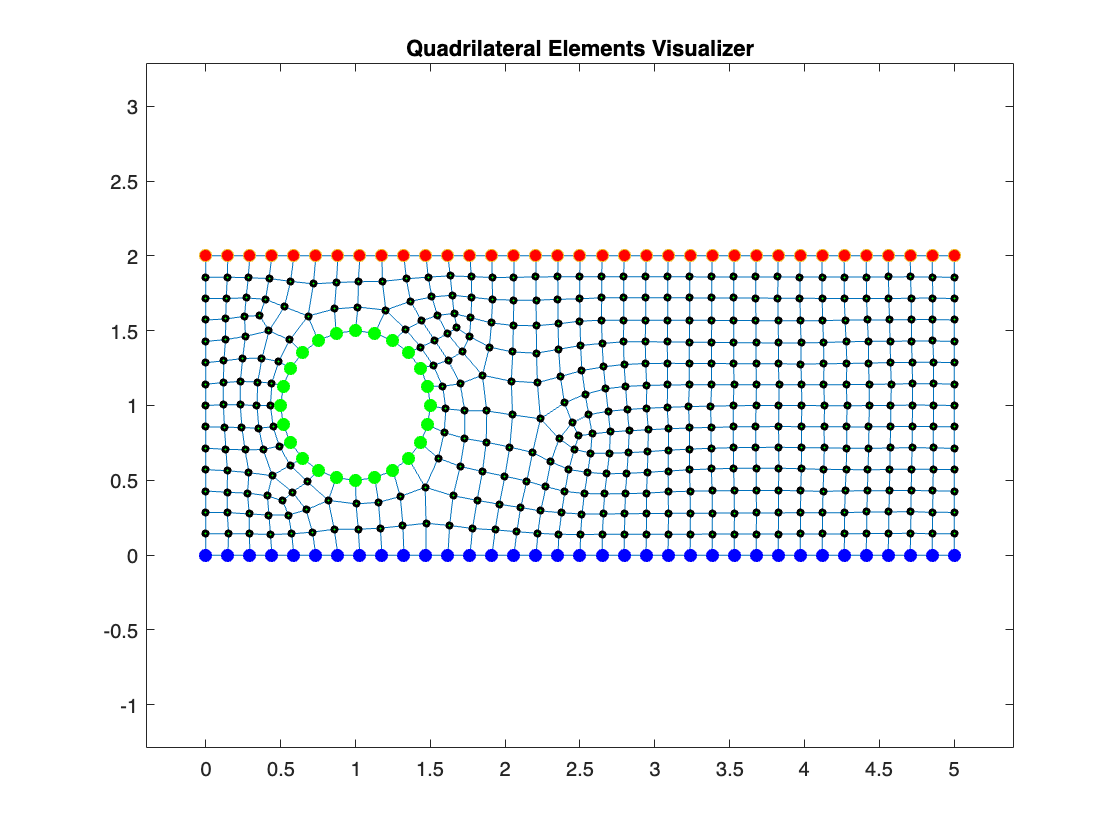

plot(nodes(nodesTop,1),nodes(nodesTop,2),'o','markerFaceColor','red')
plot(nodes(nodesBot,1),nodes(nodesBot,2),'o','markerFaceColor','blue','Color','blue')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
hold off

coeff=[a11,a12,a21,a22,a00,f];
K = zeros(numNod);
F = zeros(numNod,1);
Q = zeros(numNod,1);

for e=1:numElem
    [Ke, Fe] = bilinearQuadElement(coeff,nodes,elem,e);
    rows =[elem(e,1),elem(e,2),elem(e,3), elem(e,4)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end
Kini = K; %save a copy of the stifness matrix for the post process

**Boundary conditions**

fixedNodes = [nodesBot',nodesCirc'];
freeNodes = setdiff(1:numNod,fixedNodes);

Natural B.C.: due to convetion on the top boundary. 

%Q(freeNodes) = 0.0;

**Remark:  **we're assuming flux zero on the left and right edges, so we don't really need to set this B.C. explicitly, since  vector Q has been initialised to zero.

convNodes = nodesTop';
[K,Q] = applyConvQuad(convNodes,beta,Tinf,K,Q,nodes,elem);

Essential B.C.,

u = zeros(numNod,1);
u(nodesBot) = tempBot;
u(nodesCirc) = tempCirc;

Reduced system

Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solve the reduced system

um = Km\Im;
u(freeNodes) = um;

Post process: computation of $$Q$$'s, tabular and plot.

Q = Kini*u-F;

table.Nod = (1:numNod)';
table.X = nodes(:,1);
table.Y = nodes(:,2);
table.U = u;
table.Q = Q;

format short e
struct2table(table)

ans = 493×5 table
       Nod            X             Y             U              Q     
    __________    __________    __________    __________    ___________

    1.0000e+00    0.0000e+00    0.0000e+00    1.0000e+01    -3.4153e+00
    2.0000e+00    5.0000e+00    0.0000e+00    1.0000e+01     3.5197e-01
    3.0000e+00    1.4706e-01    0.0000e+00    1.0000e+01    -6.9653e+00
    4.0000e+00    2.9412e-01    0.0000e+00    1.0000e+01    -7.3784e+00
    5.0000e+00    4.4118e-01    0.0000e+00    1.0000e+01    -8.0379e+00
    6.0000e+00    5.8824e-01    0.0000e+00    1.0000e+01    -8.8720e+00
    7.0000e+00    7.3529e-01    0.0000e+00    1.0000e+01    -9.6676e+00
    8.0000e+00    8.8235e-01    0.0000e+00    1.0000e+01    -1.0162e+01
    9.0000e+00    1.0294e+00    0.0000e+00    1.0000e+01    -1.0213e+01
    1.0000e+01    1

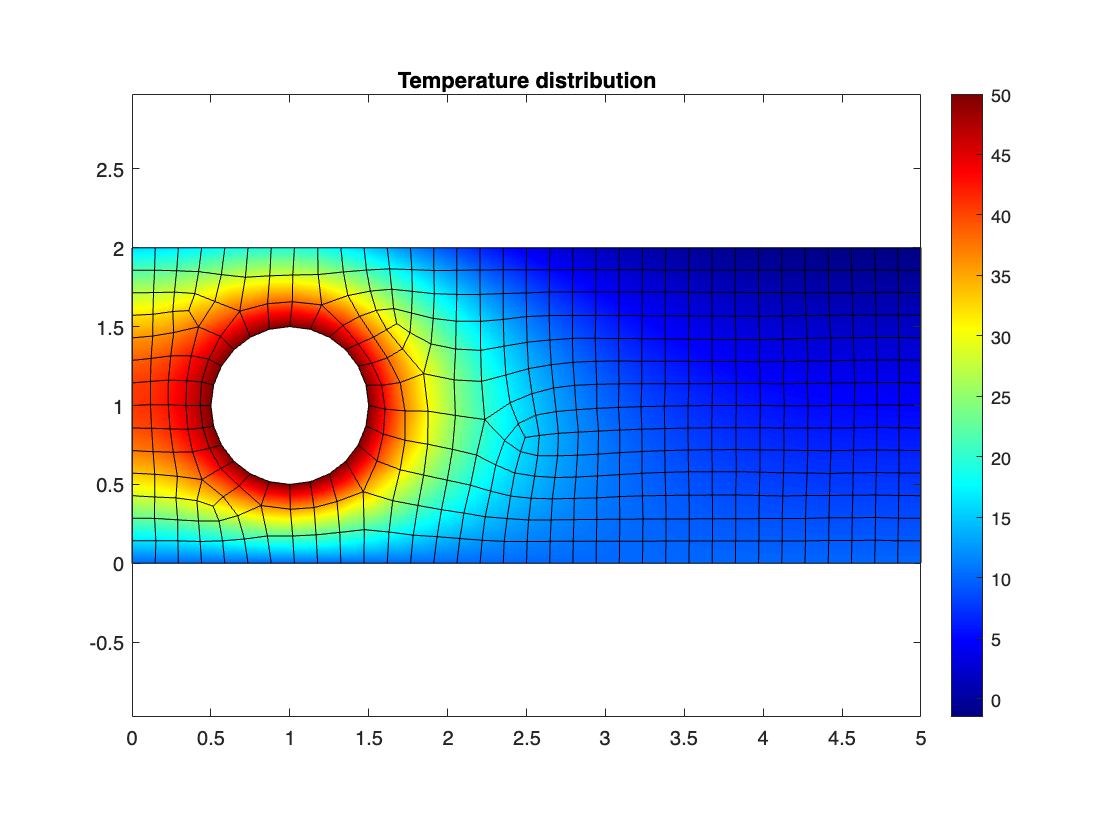


title='Temperature distribution';
colorMap = 'jet';
plotContourSolution(nodes,elem,u,title,colorMap)

## Exercise 1:

Compute the temperature for the point **p=[1.5, 1.2]**.

for e = 1:numElem
    v1 = nodes(elem(e,1),:);
    v2 = nodes(elem(e,2),:);
    v3 = nodes(elem(e,3),:);
    v4 = nodes(elem(e,4),:);
    vertexs = [v1;v2;v3;v4];
    [alphas, isInside] = baryCoordQuad(vertexs, p);
    if isInside > 0
        numElemP = e;
        numNodsP = elem(numElemP,:);
        interpTempAtP = alphas * u(numNodsP);
        break;
    end
end

fmt = ['\nInterpolated temp.\n', ...
       'Point p = (%.2f,%.2f)\n',...   
       'Element Num: %4d\n',...
       'Nodes: %d, %d, %d, %d\n', ...
       'Temp.: %11.4e%cC\n'
      ];
fprintf(fmt,p,numElemP,numNodsP,interpTempAtP,char(0176))


Interpolated temp.
Point p = (1.50,1.20)
Element Num:  248
Nodes: 288, 106, 105, 287
Temp.:  4.7120e+01°C
